# **Ejercicio 4**

## Problema T6_7.4. Integración de Simpson 3/8

clear, clc % Limpieza del entorno de trabajo

a) Escribe una función de MATLAB que utilice el método compuesto de  Simpson 3/8 para la integración de una función $f\left(x\right)$ que está dada en forma  anónima (f = @(x)).

- Véase Simpson38.m

b) Utiliza Simpson38 para resolver el siguiente problema: 

(Todos los cálculos se deben realizar con un error menor a ${10}^{-5}$)

Er = 1e-5;

En el diseño de tuberías subterráneas, es necesario estimar la temperatura del  suelo. La temperatura del suelo a distintas profundidades puede estimarse  modelando el suelo como un sólido semi-infinito inicialmente a temperatura  constante.

La temperatura a la profundidad, x, y al tiempo,  t, puede calcularse a partir de la expresión:

donde $T_s$ es la temperatura de la superficie, $T_i$ es  la temperatura inicial del suelo y  $\alpha$= 0.138$\cdot {10}^{-6}$ es la difusión térmica del  suelo. Suponiendo que $T_s$ = −15ºC y $T_i$ = 12ºC

alpha = 0.138*10^-6;
Ts = -15;
Ti = 12;
y = @(u) exp(-u.^2);

b.1) Representa gráficamente la temperatura en función del tiempo a una  profundidad de x = 0,5 m durante 40 días. Utiliza incrementos de 1 día comenzando por un valor de t próximo a cero (pero que no sea cero).

Despejando la ecuación anterior tenemos que:


$$T\left(x,\;t\right)=\left(T_i -T_s \right)\frac{2}{\sqrt{\pi }}\int_0^{\frac{x}{2\sqrt{\alpha \;t}}} e^{{-u}^2 } \textrm{du}+T_s$$


Evaluaremos la función $T\left(x,t\right)$ en $\left(x=0\ldotp 5\right)$ y $\left(0\ldotp 001<t<40\ldotp 001\right)$

x = 0.5; % En metros
t_dias = 0.001:1:41; % Días desde 0.001 hasta 40.001 en pasos de 1 (41 elementos)
t = t_dias*24*60*60; % En segundos

Para calcular la curva de temperatura se realiza la integral para cada valor de t y se sustituye en la ecuación

n = length(t);
I = zeros(n,1);
for i=1:n
    I(i) = Simpson38(y, 0, x/(2*sqrt(alpha*t(i))), Er);
end
T0_5 = (Ti - Ts) * (2/sqrt(pi)) * I  + Ts;

Finalmente se muestra en una gráfica la curva obtenida

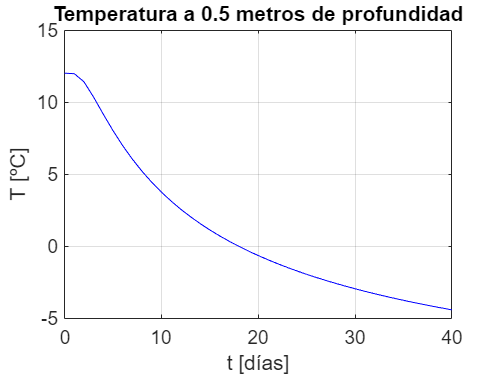

% Límites del dibujo
l1 = 0; l2 = 40;
% Gráfico
plot(t_dias, T0_5, '-b')
hold on
% Documentación y ajustes del gráfico
title('Temperatura a 0.5 metros de profundidad')
xlabel('t [días]'); ylabel('T [ºC]');
xlim([l1, l2]);
grid on
hold off

b.2) Calcula la temperatura a una profundidad x = 1m después de 30 días  (t = 2,592$\cdot {10}^6$)

Evaluaremos la función $T\left(x,t\right)$ en $\left(x=1\right)$ y $\left(t=30\right)$

x = 1; % En metros
t = 2.592e6; % En segundos

I = Simpson38(y, 0, x/(2*sqrt(alpha*t)), Er);
T1_0 = (Ti - Ts) * (2/sqrt(pi)) * I  + Ts;

fprintf("La temperatura a un metro de profundidad tras 30 días es:\n%.6f ºC", T1_0)

La temperatura a un metro de profundidad tras 30 días es:
5.598669 ºC